# RUL prediction with Regression

In this project, the intention is to build a Machine Learning model which would help to predict the Remaining Useful Life (RUL) of a machine.

## 0.0 Importing the dataset

The dataset used can be found here <link>.

Run the code in this section to load the dataset into the workspace.

clear
clc
warning('off','all');
% import the dataset
data = readtable("dataset.csv");
% create a copy of the original dataset
datacopy = data;

### 0.1 Dataset Description

- machineID - Machine ID, reads from 100 machines

- datetime - Date of telemetry

- timeincycles - Cycle reading

- voltmean24h - Volt telemetry average of the last 24h 

- rotatemean24h - Rotate telemetry average of the last 24h

- pressuremean24h - Pressure telemetry average of the last 24h 

- vibrationmean24h - Vibration telemetry average of the last 24h

- voltsd24h - Volt telemetry standard deviation of the last 24h 

- rotatesd24h - Rotate telemetry standard deviation of the last 24h

- pressuresd24h - Pressure telemetry standard deviation of the last 24h 

- vibrationsd24h - Vibration telemetry standard deviation of the last 24h

- voltmean5d - Volt telemetry average of the last 5 days 

- rotatemean5d - Rotate telemetry average of the last 5 days

- pressuremean5d - Pressure telemetry average of the last 5 days 

- vibrationmean5d - Vibration telemetry average of the last 5 days

- voltsd5d - Volt telemetry standard deviation of the last 5 days 

- rotatesd5d - Rotate telemetry standard deviation of the last 5 days

- pressuresd5d - Pressure telemetry standard deviation of the last 5 days 

- vibrationsd5d - Vibration telemetry standard deviation of the last 5 days

- error1 - Error identification 1

- error2 - Error identification 2

- error3 - Error identification 3

- error4 - Error identification 4

- error5 - Error identification 5

- comp1 - Component 1 maintenance cycle

- comp2 - Component 2 maintenance cycle

- comp3 - Component 3 maintenance cycle

- comp4 - Component 4 maintenance cycle

- model - Machine model

- age - Machine age

- DI - <unknown>

- RULWeek - Time in weeks for failure

- failure - Component identification that failed

- failed - Failed or not

- RUL - Remaining Useful Life in cycles by failure and machine

- RUL_I - Inverse RUL

## 1.0 Pre-processing

### 1.1 Drop redundant columns

- Since the RUL value of a machine is/should be independent of its ID, the attribute `machineID` is not useful for predictions. 

- Everytime `datetime` increases, `time_in_cycles` increases and there is a direct relation between them. Therefore, we would not encode datetime and can safely remove it from our training set. 

- `RULWeek` and `RULinverse` are different representations of `RUL` column, and hence just one of them is enough.

Hence, remove machineID, datetime, RULWeek and RULInverse.

datacopy = removevars(datacopy, {'machineID', 'datetime', 'RULWeek', 'RULInverse'});

### 1.2 Encoding string columns

- For columns `model` and `failure`, label encoding is required, as the datatype of these columns is string.

modelenc = ones(size(datacopy.model, 1), size(datacopy.model, 2));

for i = 1:size(datacopy.model,1)
    if strcmp(string(datacopy.model(i)), "model1")
        modelenc(i) = 1;
    elseif strcmp(string(datacopy.model(i)), "model2")
        modelenc(i) = 2;
    elseif strcmp(string(datacopy.model(i)), "model3")
        modelenc(i) = 3;
    elseif strcmp(string(datacopy.model(i)), "model4")
        modelenc(i) = 4;
    end
end

failurenc = ones(size(datacopy.failure,1),size(datacopy.failure, 2));

for i = 1:size(datacopy.failure,1)
    if strcmp(string(datacopy.failure(i)), "comp1")
        failurenc(i) = 1;
    elseif strcmp(string(datacopy.failure(i)), "comp2")
        failurenc(i) = 2;
    elseif strcmp(string(datacopy.failure(i)), "comp3")
        failurenc(i) = 3;
    elseif strcmp(string(datacopy.failure(i)), "comp4")
        failurenc(i) = 4;
    else
        failurenc(i) = 0;
    end
end

Also, the column `failed` gives the logical representation of the newly formed column `failurenc`. Therefore, we remove it as well.

datacopy = removevars(datacopy, {'model', 'failed', 'failure'});
datacopy = [datacopy(:,1:26) table(modelenc) table(failurenc) datacopy(:,27:end)];
clear modelenc; clear failurenc;

### 1.3 Merging all error columns into one

errorVec = mergeError(datacopy(:, 18:22));
datacopy = [datacopy(:, 1:17) errorVec datacopy(:,23:end)];
clear errorVec;

### 1.4 Finding correlation to realise the redundant features

We'll now realise which features (almost) repeat themselves in the dataset. We'll calculate Pearson's correlation of every column with every other column

variables = datacopy.Properties.VariableNames;
for i = 1:(size(datacopy,2)-1)
    for j = (i+1):(size(datacopy,2)-1)
        correlation = corr(datacopy(:,i), datacopy(:,j));
        if abs(correlation) > 0.6
            fprintf("%s, %s, %f\n", variables{i}, variables{j}, correlation);
        end
    end
end

voltmean5d, voltsd5d, 0.735905
rotatemean5d, rotatesd5d, -0.792681
pressuremean5d, pressuresd5d, 0.882347
vibrationmean5d, vibrationsd5d, 0.847158


#### **1.4.1 Creating plots to visualise similarities between the correlated attributes.**

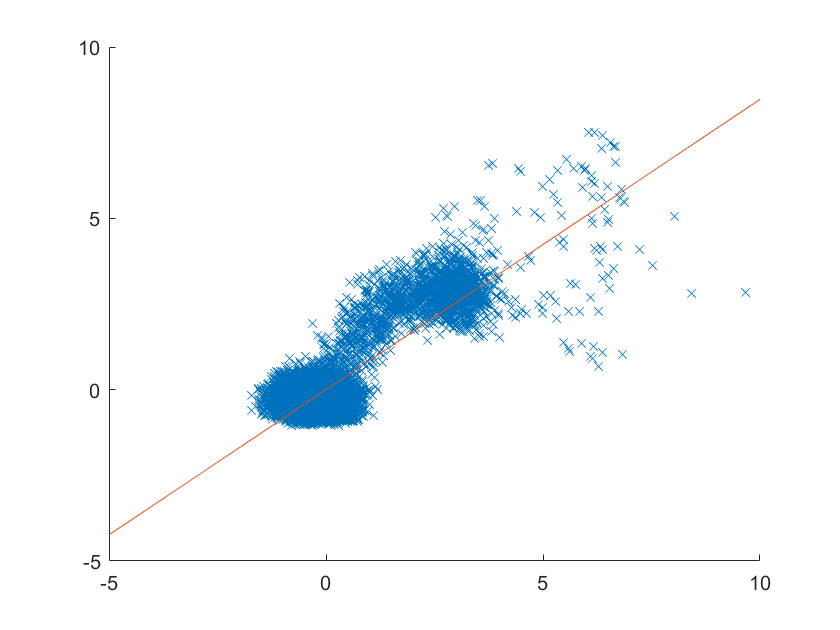

voltmean5d      = table2array(datacopy(:, "voltmean5d"));
voltsd5d        = table2array(datacopy(:, "voltsd5d"));
rotatemean5d    = table2array(datacopy(:, "rotatemean5d"));
rotatesd5d      = table2array(datacopy(:, "rotatesd5d"));
pressuremean5d  = table2array(datacopy(:, "pressuremean5d"));
pressuresd5d    = table2array(datacopy(:, "pressuresd5d"));
vibrationmean5d = table2array(datacopy(:, "vibrationmean5d"));
vibrationsd5d   = table2array(datacopy(:, "vibrationsd5d"));

abcissa = vibrationmean5d;
ordinate = vibrationsd5d;
abcissa  = table2array(zScoreNormalization(array2table(abcissa)));
ordinate = table2array(zScoreNormalization(array2table(ordinate)));
s = scatter(abcissa,ordinate,'Marker','x');
hold on;
% fit linear regression to this data to pass a line through the center.
linreg = fitlm(abcissa, ordinate);
theta = linreg.Coefficients.Estimate;
points = [-5 10];
line = theta(1) + theta(2).*points;
plot(points, line)
hold off;

#### **1.4.2 Removal of similar columns**

Now, we remove these columns, as they represent very similar values and hence, keeping both of them is redundant. 

The threshold for removal of variables is set as 0.7.

for i = 1:(size(datacopy,2)-1)
    for j = (i+1):(size(datacopy,2)-1)
        if abs(corr(datacopy(:,i), datacopy(:,j))) > 0.7
            datacopy = removevars(datacopy, j);
        end
    end
end

## 2.0 Train-test split

We now break the data into training and testing sets.

t = cvpartition(height(datacopy),'HoldOut',0.3);
idx = t.test;
dataTrain = datacopy(~idx, :);
dataTest = datacopy(idx, :);

**Visualising dataTrain/dataTest:**

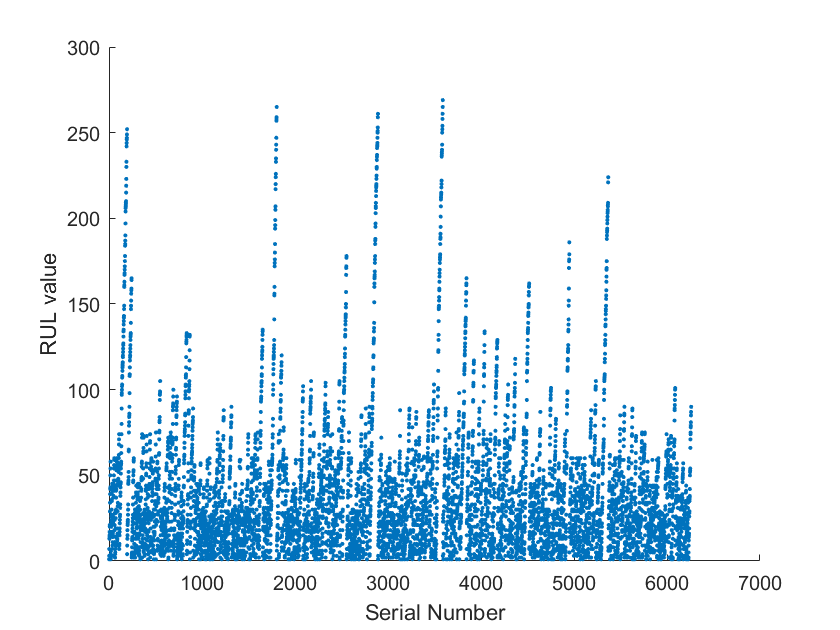

scatter((1:height(dataTest)), dataTest.RUL, 'Marker', '.');
hold on;
xlabel("Serial Number");
ylabel("RUL value");
hold off;

## 3.0 Feature scaling: Standardization (z-score normalization)

### 3.1 Normalizing train data and getting the params

It is necessary for us to normalize all the numeric columns so that they occur in a similar fashion for the optimizers to solve them.

mu = zeros(size(dataTrain,2),1);
sigma = zeros(size(dataTrain,2),1);
for i = 1:size(dataTrain,2)
    [dataTrain(:, i), mu(i), sigma(i)] = zScoreNormalization(dataTrain(:, i));
end

### 3.2 Normalizing test data on the basis of parameters found

Since this data is to be treated as new to the model, we use normalizing parameters found from the training set.

dataTestArray = table2array(dataTest);
variables = dataTest.Properties.VariableNames;
yTest = table2array(dataTest(:, end));
for i=1:height(dataTestArray)
    dataTestArray(i, :) = (dataTestArray(i, :)-mu')./sigma';
end
dataTest = array2table(dataTestArray, "VariableNames", variables);

## 4.0 Training Models

**General variables:**

predictorNames = dataTrain.Properties.VariableNames(1:(end-1));
predictors = dataTrain(:, predictorNames);
response = dataTrain.RUL;

**Note: **Test Error is measured in RMSE (Root Mean Squared Error)

### 4.1 Linear Regression Model

linMdl = fitlm(dataTrain);
linMdl.Rsquared.Ordinary*100 % how much percent the given data fits to the model

ans = 57.2399

The variables having `pValue` > 0.05 don't contribute much to the model, i.e., the less the pValue, the better.

Their corresponding `Estimate` values are also close to zero.

removevars(linMdl.Coefficients, {'tStat', 'SE'})

ans = 23×2 table
                         Estimate        pValue  
                        ___________    __________

    (Intercept)         -2.4991e-15             1
    timeInCycles           0.081415    5.1423e-48
    voltmean24h          -0.0043527        0.4881
    rotatemean24h          0.013831      0.027891
    pressuremean24h       -0.015218      0.018133
    vibrationmean24h       -0.02618    3.5717e-05
    voltsd24h             0.0087443       0.10764
    rotatesd24h          -0.0085597       0.11864
    pressuresd24h        0.00033086       0.95316
    vibrationsd24h       -0.0013063       0.81298
    voltmean5d           -0.0037963       0.54695
    rotatemean5d           -0.00985       0.11861
    

RMSE: 25.781117


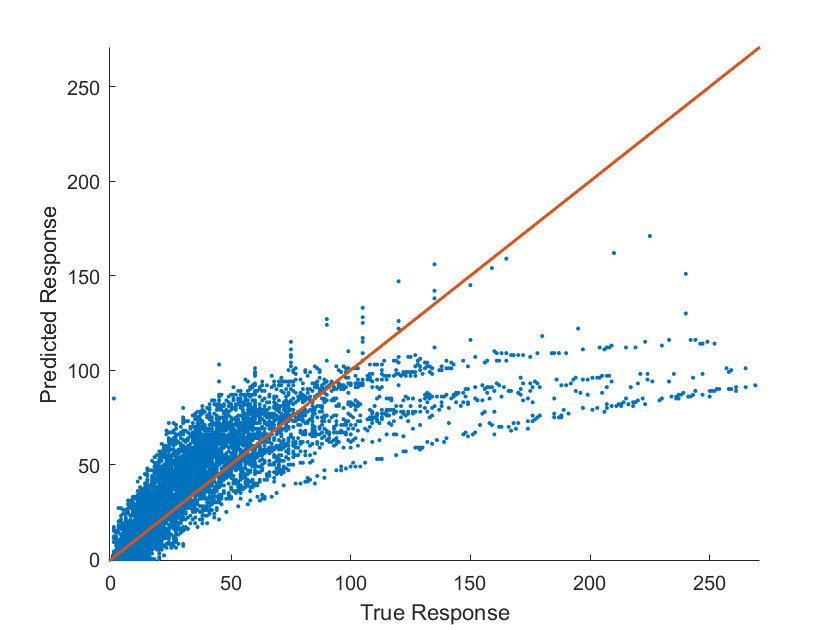

rulLinMdl = handle(linMdl, dataTest(:, predictorNames), sigma, mu);
%plot function
plotResult(yTest, rulLinMdl);

**Inference:**

*The model doesn't work very well for both low and high values of RUL, and also tends to predict relatively ****less ****values for the given ****high values. ***

*This can be due to the linearity of the model which restricts it to fit to changing trends of the data.*

### 4.2 Support Vector Regressor

RMSE: 29.216303


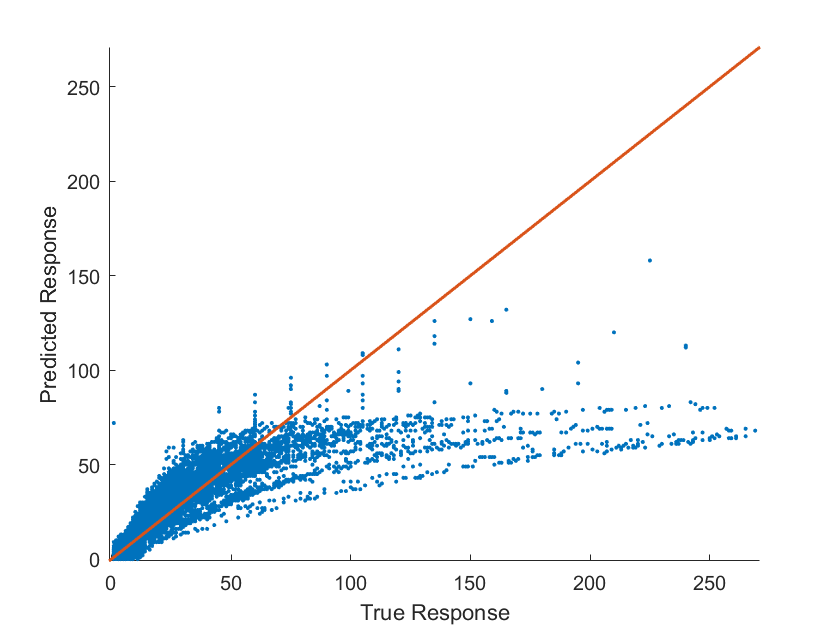

responseScale = iqr(response);
if ~isfinite(responseScale) || responseScale == 0.0
    responseScale = 1.0;
end
boxConstraint = responseScale/1.349;
epsilon = responseScale/13.49;
svmMdl = fitrsvm(...
    predictors, ...
    response, ...
    'KernelFunction', 'linear', ...
    'PolynomialOrder', [], ...
    'KernelScale', 'auto', ...
    'BoxConstraint', boxConstraint, ...
    'Epsilon', epsilon, ...
    'Standardize', false);

rulSvmMdl = handle(svmMdl, dataTest(:, predictorNames), sigma, mu);
plotResult(yTest, rulSvmMdl);

**Inference:**

*The model also isn't predicting very well for both low and high values of RUL.*

*Compared to Linear Regression, it worked better for the lower values of RUL, but worked even worse for higher values as the majority of the higher true values are predicted between 40-60, whereas in Linear Regression they were in between 80-120, making it's accuracy even less than Linear Regression.*

*This can be due to the the fact that SVM tries to fit a hyperplane in an n-dimensional space and that hyperplane (like the linear model), resists changes in an ongoing fashion of data.*

*Therefore, we now need an Algorithm that is independent of "plane" complexity. Hence, we'll now train a Tree.*

### 4.3 Fine Tree Model

RMSE: 7.287610


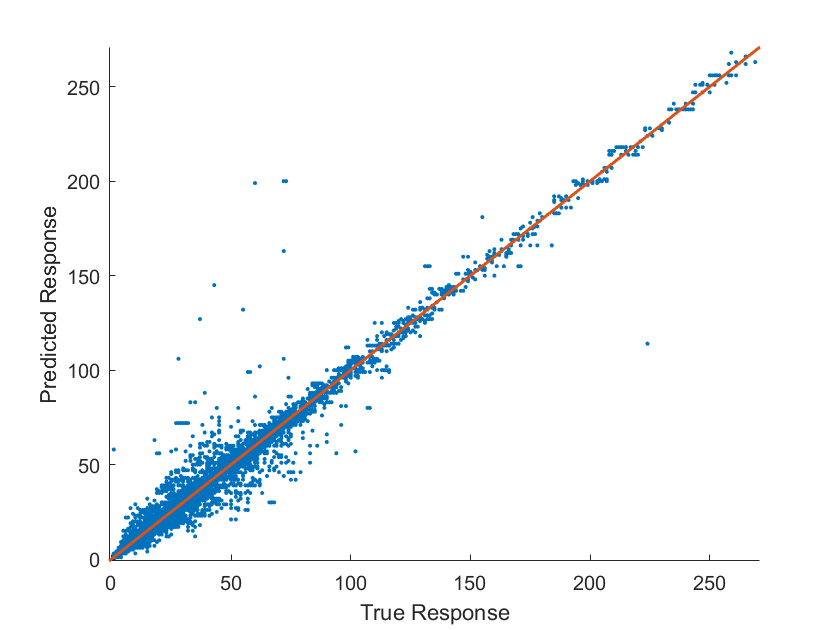

fineTreeMdl = fitrtree(...
    predictors, ...
    response, ...
    'MinLeafSize', 4, ...
    'Surrogate', 'off');
rulTreeMdl = handle(fineTreeMdl, dataTest(:, predictorNames), sigma, mu);
%plot function
plotResult(yTest, rulTreeMdl);

**Inference:**

*The model holds good for both low and high values of RUL. *

*Since this algorithm has decision boundries for different cases in the data and is independent of hyperplanes and linearity, it worked much better for our data.*

*It is observable that some values are very differently predicted - for eg. the value 73 is predicted as 200, but is still acceptable.*

### 4.4 Boosted Trees : Ensemble Learning

RMSE: 16.613743


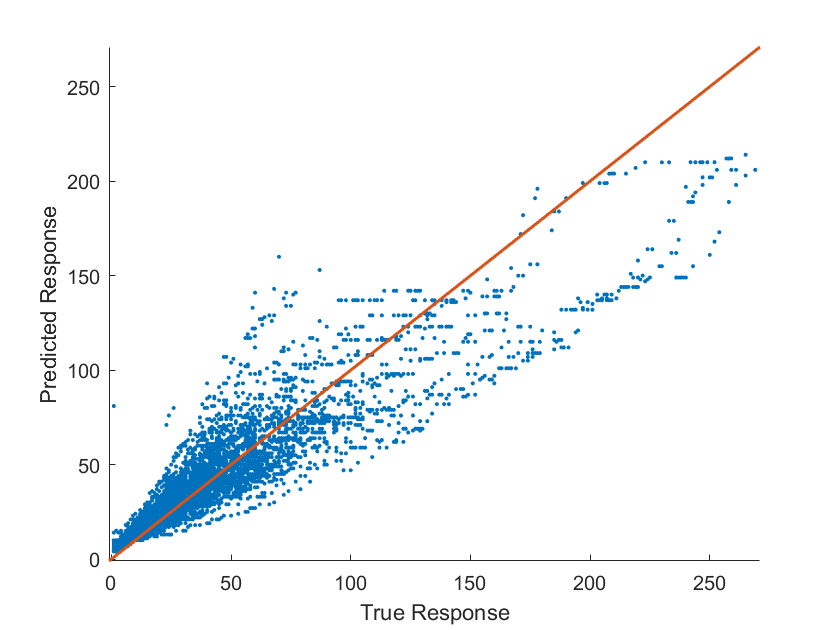

template = templateTree('MinLeafSize', 8);
boostedMdl = fitrensemble(...
    predictors, ...
    response, ...
    'Method', 'LSBoost', ...
    'NumLearningCycles', 30, ...
    'Learners', template, ...
    'LearnRate', 0.1);
rulBoostMdl = handle(boostedMdl, dataTest(:, predictorNames), sigma, mu);
% plot
plotResult(yTest, rulBoostMdl);

**Inference:**

*The model holds good for lower values of RUL, but disperse away from the expected for the second quartile of RUL.*

*It might be due to the fact that ensemble learners try to fit different decision boundaries with a wide variety of hyperparameters and then form a collective result, and this might do bad if the data is fragile and tend towards a particular set of hyperparameters. This can also be the reason why Fine Tree worked better than Boosted Trees.*

# Model Diagnosis

t = cvpartition(height(datacopy), 'HoldOut', 0.99);
random = datacopy(t.test, :);
r = cvpartition(height(random), 'HoldOut', 0.35);
rand = r.test;
diaT = random(rand, :);
diaV = random(~rand, :);

Here, the number of training examples are kept less in training set and more in cv set to estimate 

[diaT, diaMu, diaSigma] = zScoreNormalization(diaT);
diaV = normTest(diaV, diaMu, diaSigma);

## Learning plots

model = 4 ;
[errt, errv] = diaError(model, diaT, diaV, diaSigma, diaMu);

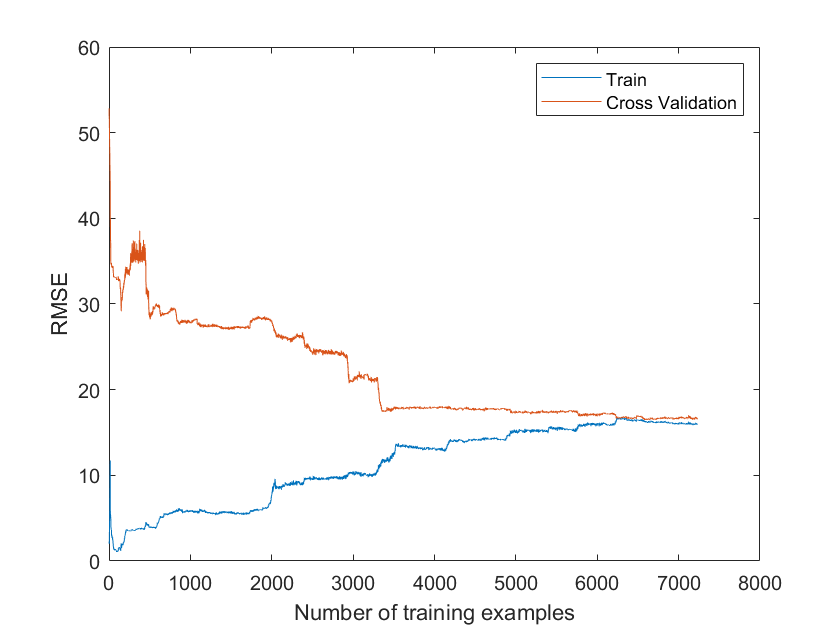

plotLearning(errt, errv);
axis([0 8000 0 60])

### Results and Inference:

- Linear Regression:

*The gap between training sets and cross validation set errors is not significant, but the RMSE value is high. That means, the model can neither predict the train set well, nor does it predict the cross validation set well.*

*Therefore, the model suffers from ****High Bias**** (underfitting), that means the parameters are just too simple for it too fit. Adding polynomial features of significant columns and training that with a neural network might help.*

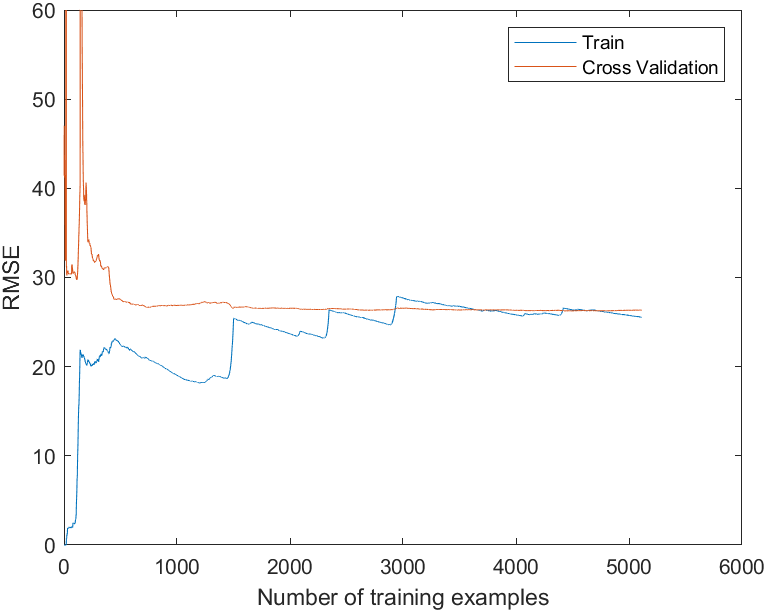

- SVR:

*Similar to the case of Linear Regression, when m is set to 5000, the Training error and the Cross Validation error comes close but they both are magnitude-wise very high. Therefore, this model also suffers from ****high bias****. Hypermeter Tuning can help to raise the complexity of the model. Another option is to train a neural network with complex polynomial features.*

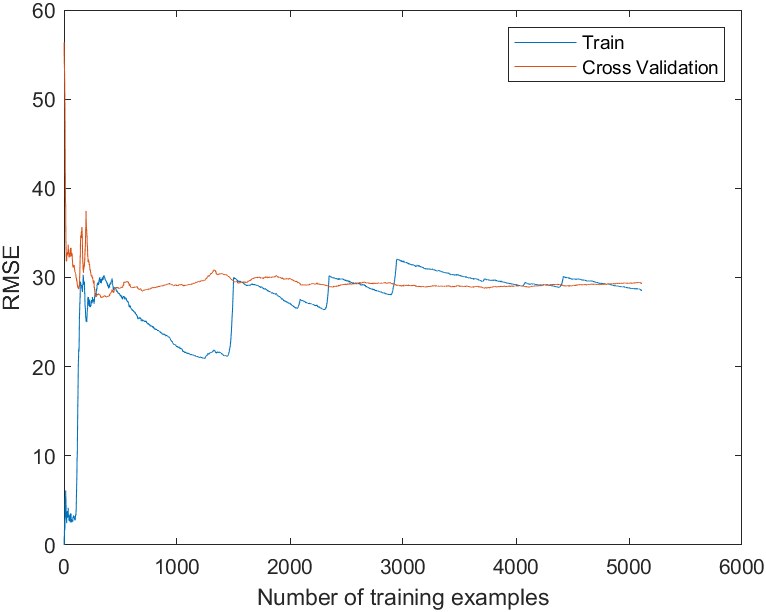

- *Fine tree:*

*The errors for both training and cross validation set is very less as compared to others. (8-12) and evidently, this model neither suffers from ****High Bias****, nor ****High Variance, ****and hence the performance of this algorithm cannot be increased. It is also observable from the figure below that the cross validation error decreases as number of training examples increases. Therefore, adding more examples to the training set is likely to increase the model's performance.*

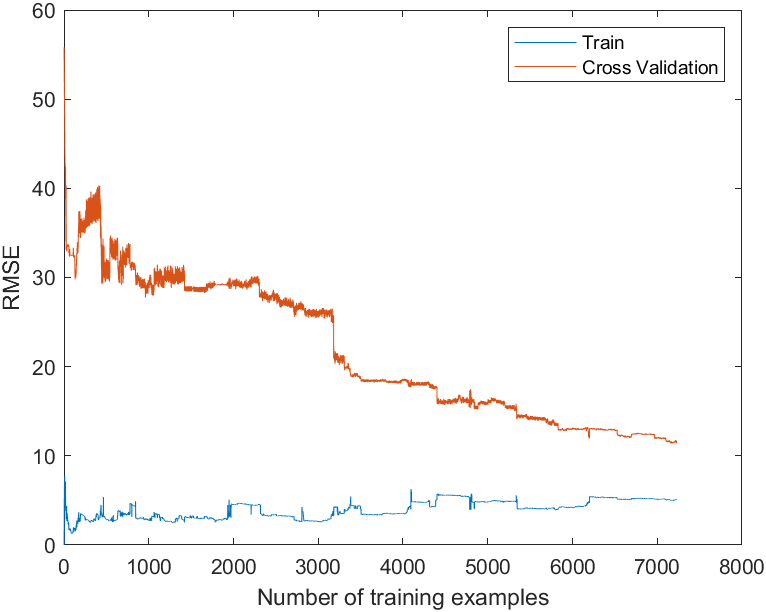

- Boosted Trees:

The ensemble learning model similar to linear regression, can't seem to minimize either of training and cross validation sets. and thus suffers from high bias, i.e., the model is too simple as of now. Since it is an ensemble model, Hypermeter tuning is likely to turn out slow in it. It's RMSE value is more than Fine Tree and less than Linear Regression and SVR.

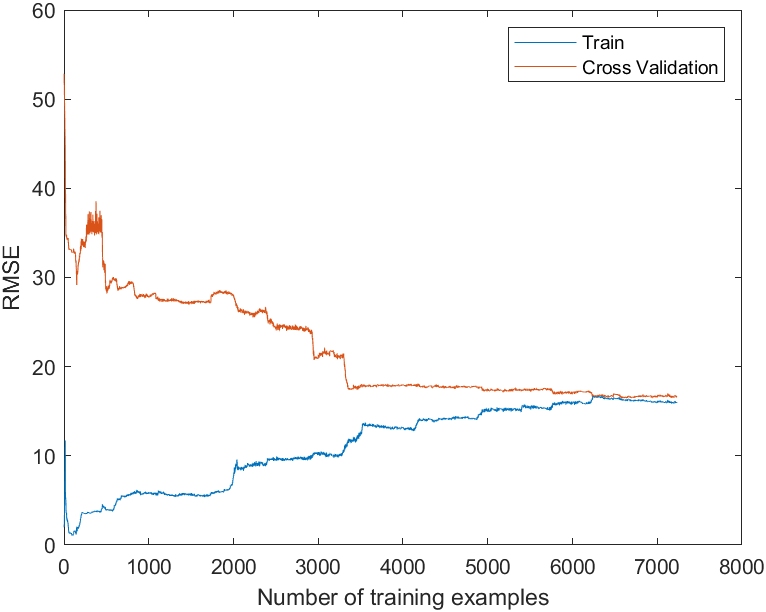

# Local Functions

### - Round off the results

function final = decorate(rul)
    final = zeros(size(rul));
    for i=1:size(rul)
        if rul(i) < 0
            final(i) = 0;
        else
            final(i) = round(rul(i));
        end
    end
end

### - Z score Normalization

function [col, mu, st] = zScoreNormalization(c)
    s = c.Properties.VariableNames;
    c = table2array(c);
    % z-score normalization which is based on mean and standard deviation of
    %                             input - mean of column
    % data calculated as output = -----------------------
    %                             std deviation of column
    mu = mean(c);
    st = std(c);
    col = (c-mu)./st;
    col = array2table(col, 'VariableNames', s);
end

### - Covariance

function a = cov(X, Y)
    a = sum((X- mean(X)).*(Y-mean(Y)))/(size(X,1)-1);
end

### - Correlation

function a = corr(X, Y)
    X_array = table2array(X);
    Y_array = table2array(Y);
    a = cov(X_array,Y_array)/(std(X_array)*std(Y_array));
end


### - Merge all error columns into one

function errorVec = mergeError(errors)
    errors = table2array(errors);
    errorVec = zeros(size(errors,1),1);
    for i=1:size(errors,1)
        errorVec(i) = errors(i,1) || errors(i,2) || errors(i,3) || errors(i,4) || errors(i,5);
    end
    errorVec = array2table(errorVec);
end

### - Denormalize

function rul = denorm(r, sigma, mu)
    if istable(r)
        r = table2array(r);
    end
    rul = r.*sigma(end) + mu(end);
end

### - Plot True vs Predicted

function plotResult(yTest, rul)
    scatter(yTest, rul,'Marker', '.');
    hold on;
    xp = linspace(min(yTest)-2, max(yTest)+2);
    p = plot(xp,xp);
    p.LineWidth =1.5;
    xlabel("True Response");
    ylabel("Predicted Response");
    xlim([-1 xp(end)])
    ylim([-1 xp(end)])
    fprintf("RMSE: %f\n", error(rul, yTest));
    hold off;
end

### - Error

function e = error(rul, yTest)
    e = sqrt(sum(( rul - yTest ).^2)/numel(yTest));
end

### - Predict, Denormalize, and Decorate

function rul = handle(mdl, X, sigma, mu)
    rul = predict(mdl, X);
    rul = denorm(rul, sigma, mu);
    rul = decorate(rul);
end

### - Learning error vectors

function [errorT, errorV] = diaError(model, Xtrain, Xval, diaSigma, diaMu)
    m = height(Xtrain);
    errorT = zeros(m, 1);
    errorV = zeros(m, 1);
    for i=1:m
        if model == 1
           dMdl = fitlm(Xtrain(1:i, :));
        elseif model == 2
            responseScale = iqr(table2array(Xtrain(1:i, "RUL")));
            if ~isfinite(responseScale) || responseScale == 0.0
                responseScale = 1.0;
            end
            boxConstraint = responseScale/1.349;
            epsilon = responseScale/13.49;
            dMdl = fitrsvm(...
                Xtrain(1:i, :), ...
                "RUL", ...
                'KernelFunction', 'linear', ...
                'PolynomialOrder', [], ...
                'KernelScale', 'auto', ...
                'BoxConstraint', boxConstraint, ...
                'Epsilon', epsilon, ...
                'Standardize', false);
        elseif model == 3
           dMdl = fitrtree(...
                    Xtrain(1:i, :), ...
                    "RUL", ...
                    'MinLeafSize', 4, ...
                    'Surrogate', 'off');
        else
            template = templateTree('MinLeafSize', 8);
            dMdl = fitrensemble(...
                Xtrain(1:i, :), ...
                "RUL", ...
                'Method', 'LSBoost', ...
                'NumLearningCycles', 30, ...
                'Learners', template, ...
                'LearnRate', 0.1);
        end
        rulT = handle(dMdl, Xtrain(1:i, 1:end-1), diaSigma, diaMu);
        rulV = handle(dMdl, Xval, diaSigma, diaMu);
        yTrainTrue = denorm(Xtrain(1:i, "RUL"), diaSigma, diaMu);
        yValidTrue = denorm(Xval.RUL, diaSigma, diaMu);
        errorT(i)= error(rulT, yTrainTrue);
        errorV(i)= error(rulV, yValidTrue);
    end
end

### - Normalize Test data

function diaV = normTest(diaV, mu, sigma)
    diaVArray = table2array(diaV);
    tempVars = diaV.Properties.VariableNames;
    for i=1:height(diaVArray)
        diaVArray(i, :) = (diaVArray(i, :)-mu)./sigma;
    end
    diaV = array2table(diaVArray, "VariableNames", tempVars);
end

### - Plot Learning Curves

function plotLearning(errt, errv)
    m = height(errt);
    plot(1:m, errt, 1:m, errv);
    legend('Train', 'Cross Validation')
    xlabel('Number of training examples')
    ylabel('RMSE')
    axis([0 6000 0 60])
end